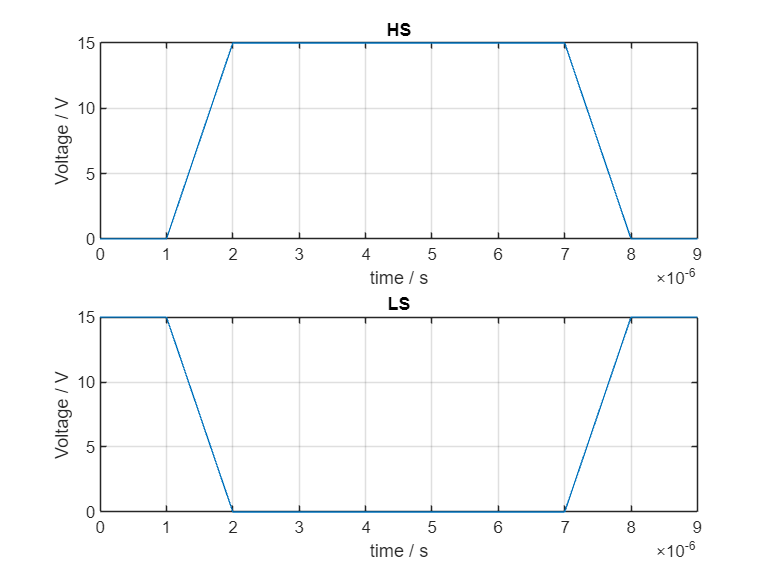

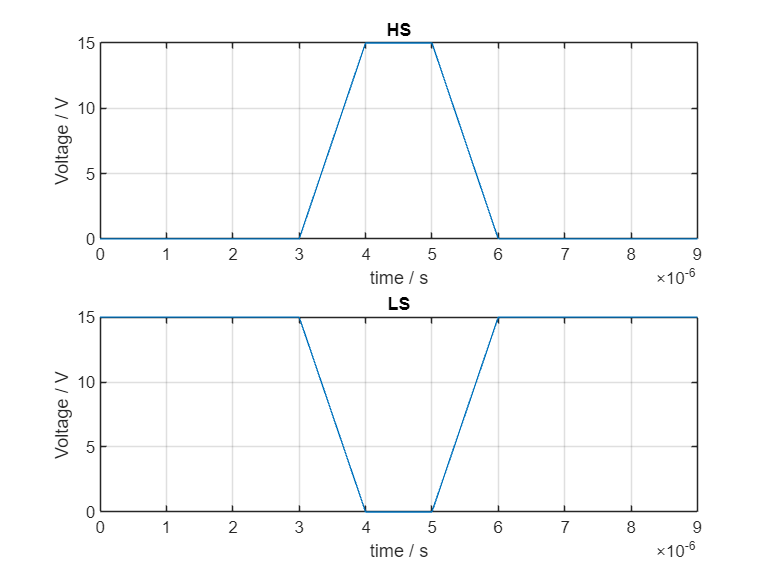

clear all;
close all;

moveFwdMin = 1e-6;
moveFwdMax = 300e-6;

hb1 = HalfBridge(15,0);
hb1.init(-1);

hb2 = HalfBridge(15,0);
hb2.init(-1);

hbridge = HBridge(hb1, hb2);

%% begin
hbridge.moveForwardInTime(0.000001);

hbridge.hb1.swtch(1,1e-6);
hbridge.hb2.swtch(-1,1e-6);

hbridge.moveForwardInTime(0.000001);

hbridge.hb1.swtch(1,1e-6);
hbridge.hb2.swtch(1,1e-6);


hbridge.moveForwardInTime(0.000001); % 6

hbridge.hb1.swtch(1,1e-6);
hbridge.hb2.swtch(-1,1e-6);

hbridge.moveForwardInTime(0.000001); % 8

hbridge.hb1.swtch(-1,1e-6);
hbridge.hb2.swtch(-1,1e-6);


hbridge.moveForwardInTime(1e-6); % 8

clf;
hbridge.plotAllSignals();


hbridge.exportAllSignalsToPWL();

PWL-Datei "LeftHB_HS.txt" erfolgreich erstellt.
PWL-Datei "LeftHB_LS.txt" erfolgreich erstellt.
PWL-Datei "RightHB_HS.txt" erfolgreich erstellt.
PWL-Datei "RightHB_LS.txt" erfolgreich erstellt.
